clear;
global SAVE_EXT;
global SAVE_DIR;
SAVE_EXT = "png";% figure saving conf (png, eps, etc...)
SAVE_DIR = "lab3/tex/images/";
mkdir(SAVE_DIR)

## Task 1

T_1_real = 0.85;
T_2_real = 0.95;
T_1 = T_1_real;
T_2 = T_2_real;
perturb_type = 0;

## Task 2

T = T_1 / 2;
input_type= 0;
d_1 = exp(-T/T_1);
d_2 = exp(-T/T_2);
reg_num = [1 -d_1-d_2 d_1*d_2];

function modeling(exp_name)
    global SAVE_EXT;
    global SAVE_DIR;
    sim_res = sim("lab3/lab3.slx", 15);
    clf;
    title("System state")
    hold on
    plot(sim_res.g.time, sim_res.g.data(:,1), 'LineWidth', 2, 'Color', 'red', 'LineStyle', '--')
    plot(sim_res.x.time, sim_res.x.data(:,1), 'LineWidth', 2, 'Color', 'blue', 'LineStyle', '-')
    grid on
    legend(["$g(t)$", "$x(t)$"], Interpreter="latex")
    hold off
    exportgraphics(gcf, SAVE_DIR + exp_name + "_state." + SAVE_EXT)
end

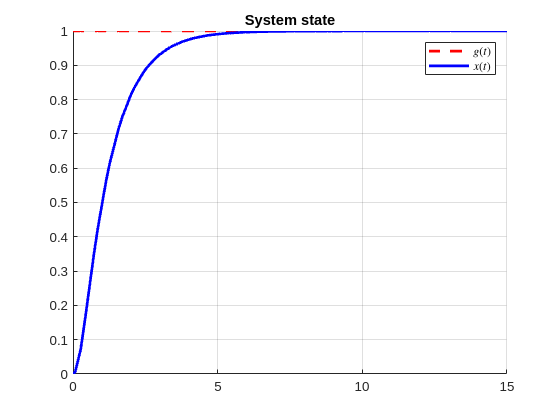

q0 = 2;
modeling("task2__q0_2")

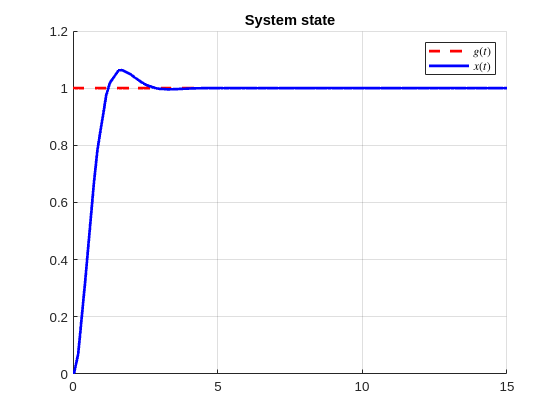

q0 = 4;
modeling("task2__q0_4")

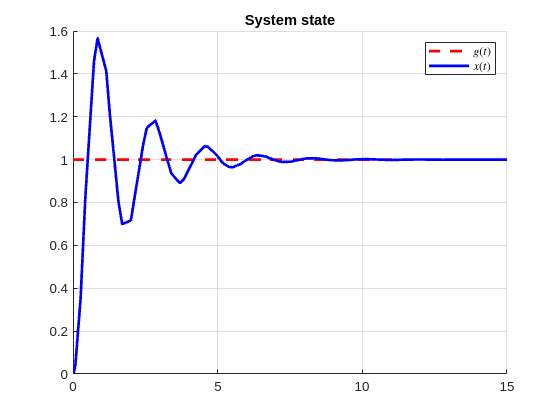

q0 = 10;
modeling("task2__q0_10")

## Task 3

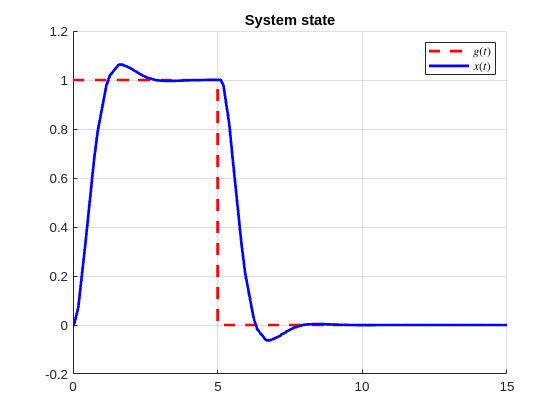

q0 = 4;
input_type = 1;
modeling("task3__step_input")

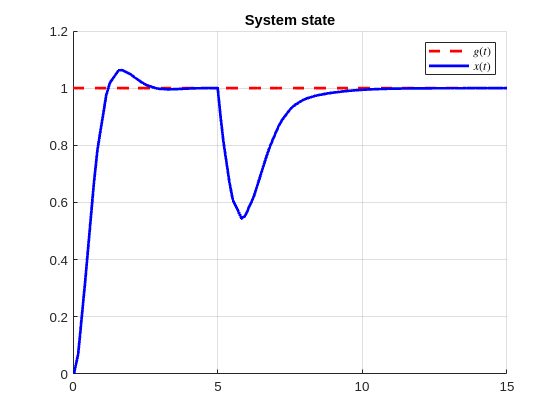

input_type = 0;
perturb_type = 1;
modeling("task3__step_perturb")

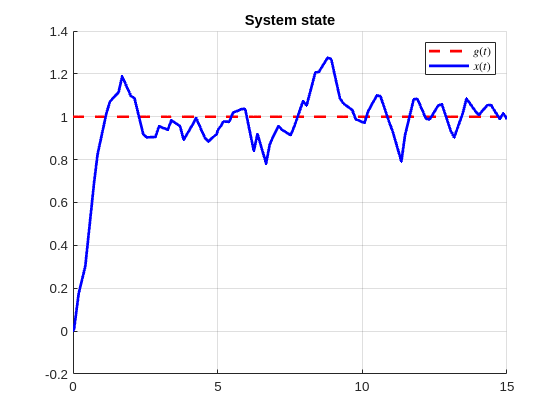

input_type = 0;
perturb_type = 2;
modeling("task3__noise_perturb")

## Task 4

T = T_1 / 4;
d_1 = exp(-T/T_1);
d_2 = exp(-T/T_2);
reg_num = [1 -d_1-d_2 d_1*d_2];
perturb_type = 1;
input_type = 0;

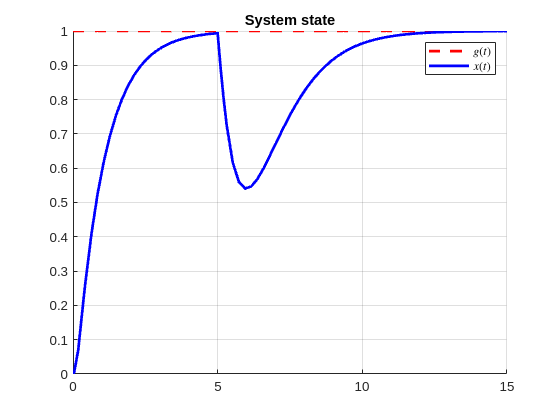

modeling("task4__step_perturb")

## Task 5

T = T_1_real / 2;
T_2 = 0.8 * T_2_real;
d_1 = exp(-T/T_1);
d_2 = exp(-T/T_2_real);
reg_num = [1 -d_1-d_2 d_1*d_2];
perturb_type = 1;
input_type = 0;

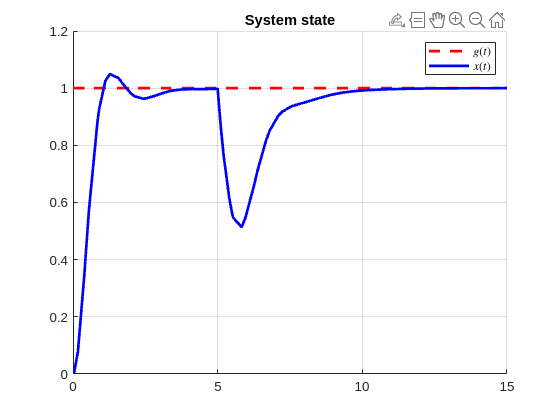

modeling("task5__decreased")

T_2 = 1.2 * T_2_real;
d_1 = exp(-T/T_1);
d_2 = exp(-T/T_2_real);
reg_num = [1 -d_1-d_2 d_1*d_2];
perturb_type = 1;
input_type = 0;

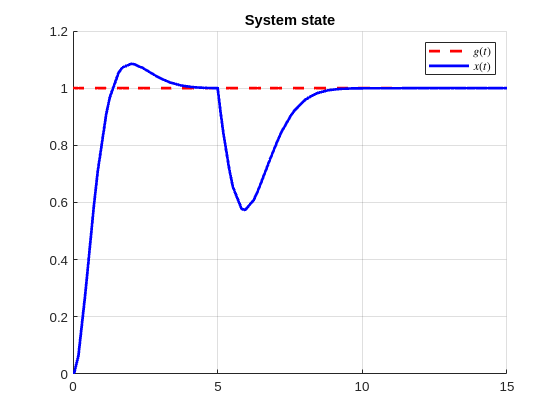

modeling("task5__increased")